# ANALYSIS OF BIOMEDICAL DATA AND SIGNALS PROJECT - INVESTIGATION OF BIOCONCENTRATION

## Introduction

**Team Member 1: MAHTA MEHRPARVAR **

**Team Member 2: MERT ALPEREN BEŞER **

**Group: 7B**

Our goal in this project is to identify the type of bioaccumulation for a given molecule using machine learning techniques. We have a [dataset](https://archive.ics.uci.edu/ml/datasets/QSAR+Bioconcentration+classes+dataset) [3-4] with 10 features and 3 classes, which represent the different types of bioaccumulation, for each 779 molecules: 

1 - Mainly concentrated in lipid tissues

2 - Additional storage sites (e.g. proteins) and 

3 - Metabolized/cleared.

To achieve this goal, we will be using multiple machine learning methods including Deep Neural Networks, Multinomial Logistic Regression, Naive Bayes and Linear Discriminant Analysis (LDA).

We have chosen to use these methods because they are suitable for solving classification problems and also they are powerful and generalizable models that can handle high-dimensional data. Furthermore, by using multiple methods and comparing their performance, we can gain a better understanding of the strengths and limitations of each method and select the one that performs best on our specific dataset.

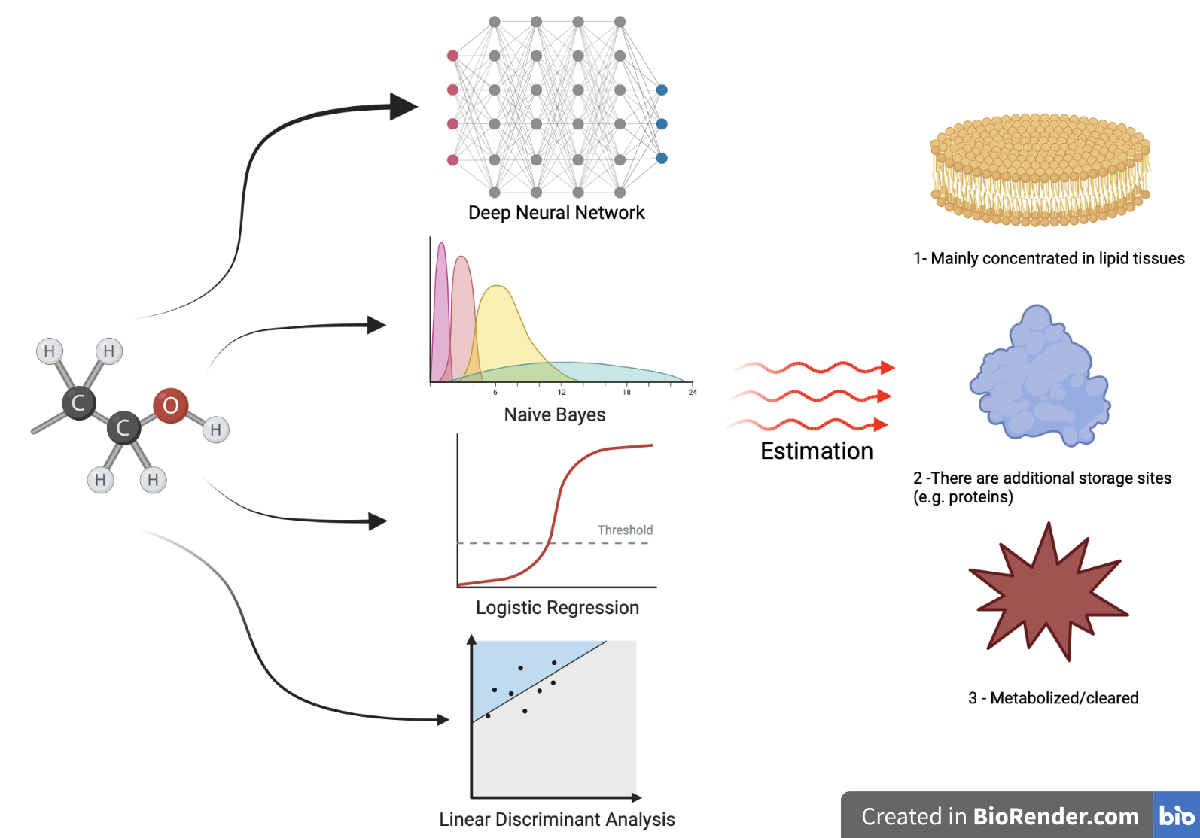

## Description of the dataset 

*Bioaccumulation of classes*

- Mainly concentrated in lipid tissues

- There are additional storage sites (e.g. proteins)

- Metabolized/cleared

*Significant Features for Training*

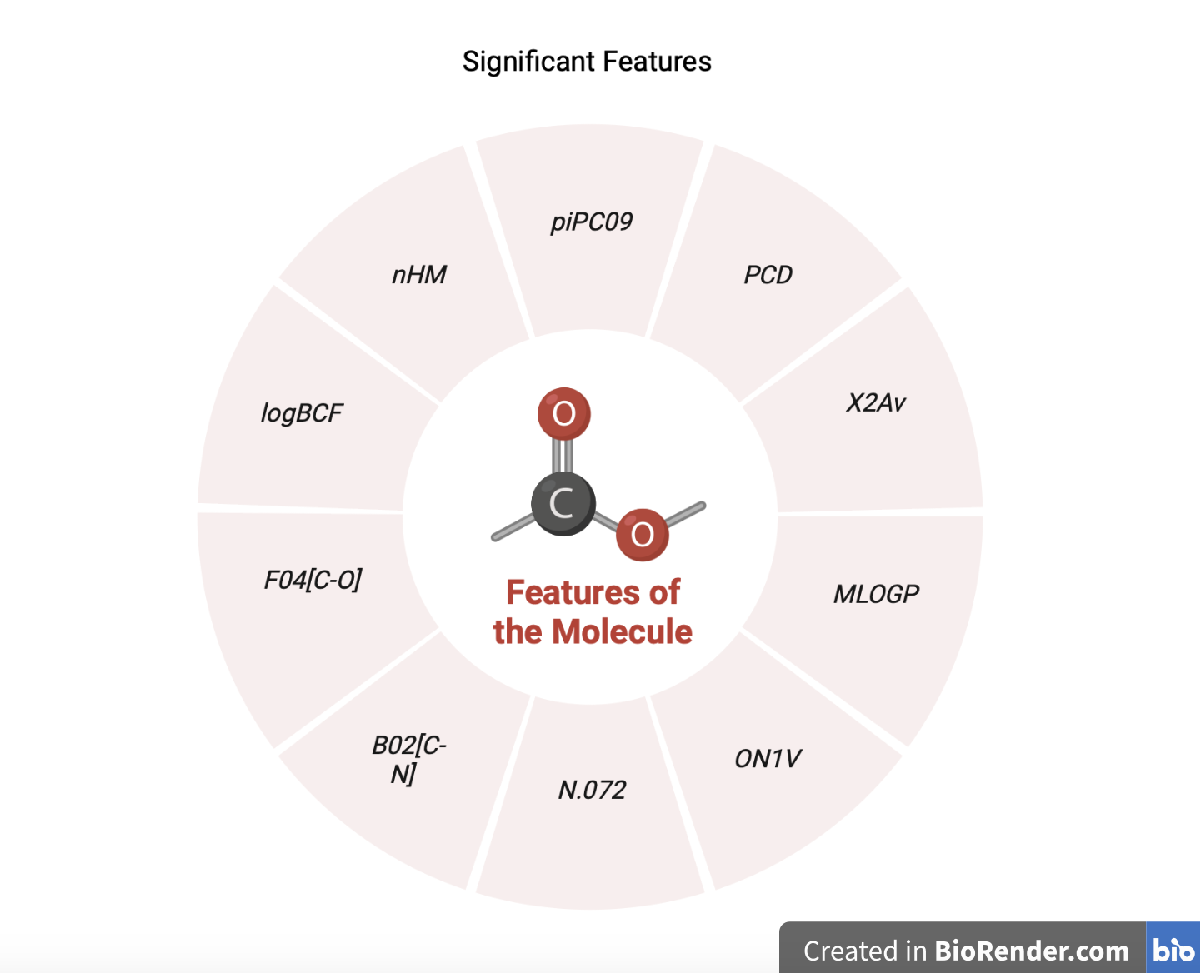

- *nHM* - number of heavy atoms (integer)

- *piPC09* - molecular multiple path count (numeric)

- *PCD* - difference between multiple path count and path count (numeric)

- *X2Av* - average valence connectivity (numeric)

- *MLOGP* - Moriguchi octanol-water partition coefficient (numeric)

- *ON1V* - overall modified Zagreb index by valence vertex degrees (numeric)

- *N.072* - Frequency of RCO-N< / >N-X=X fragments (integer)

- *B02[C-N]* - Presence/Absence of C-N atom pairs (binary)

- *F04[C-O]* - Frequency of C-O atom pairs (integer)

- *logBCF* - Bioconcentration Factor in log units (numeric)

Unsignificant Features

- CAS

- SMILES

Also "SET" variable states whether the molecules' data belongs to train or test data.

% Extracting the data from csv file
data = readtable("data.csv")

data = 779×14 table
         CAS                          SMILES                        Set       nHM    piPC09    PCD     X2Av    MLOGP    ON1V    N_072    B02_C_N_    F04_C_O_    Class    logBCF
    ______________    _______________________________________    _________    ___    ______    ____    ____    _____    ____    _____    ________    ________    _____    ______

    {'100-02-7'  }    {'O=[N+](c1ccc(cc1)O)[O-]'            }    {'Train'}     0         0     1.49    0.14    1.35     0.72      0         1        

### Some additional notes about the features

- MLOGP, the Moriguchi octanol-water partition coefficient, is a measure of the lipophilicity (fat solubility) of a compound and can be used to predict whether it is likely to be concentrated in lipid tissues. A compound with a high MLOGP value is more likely to be concentrated in lipid tissues [1].

- logBCF, the bioconcentration factor in log units, is a measure of the accumulation of a chemical in the tissues of living organisms and can be used to predict whether a compound is likely to accumulate in specific tissues [2].

- The presence or absence of certain functional groups, such as oxygen or nitrogen atoms, can also provide some indication of the metabolism and clearance of a compound. For example, the presence of oxygen atoms may suggest that a compound can be metabolized by enzymes that contain oxygen, while the presence of nitrogen atoms may suggest that a compound can be metabolized by enzymes that contain nitrogen. However, it is important to note that the metabolism and clearance of a compound can be influenced by many other factors in addition to its structural features.

### Preprocessing of the Data

% Extracting Class Labels
Y = data.Class;

% Get Desired Data
X = data(:,4:end);

% Remove Class Column from Features
X(:,'Class') = [];

% Convert table to array to use PCA
X_ = table2array(X);

% Choose data as Normalize or Unnormalized data 
X_ = zscore(X_);;

### PCA


$$y\cong \sum_{i=1}^p \vec{u_i } \;\ldotp x_i$$


Principal Component Analysis (PCA) is a statistical technique used to reduce the dimensionality of a data set while retaining as much information as possible. The basic idea behind PCA is to find a new set of orthogonal axes (principal components) that capture the most variation in the data. These new axes are ordered by the amount of variation they capture, with the first principal component capturing the most variation, the second principal component capturing the second most, and so on [5].

1) Standardized data


$$z_i =\frac{y_i -\mu_i }{\sqrt{\sigma_i^2 }}$$


2) Covariance matrix


$$\textrm{cov}\left(x,y\right)=\frac{1}{n-1}\sum_{i=1}^n \left(x_i -\overset{-}{x} \right)\left(y_i -\overset{-}{y} \right)$$


3) Eigenvalue and eigenvector calculation


$$A\vec{v} =\lambda \vec{v}$$


4) Projection onto the new axes:


$$Y=z_i V$$


where $z_i$ is the standardized data (as a matrix), $V$ is the matrix of eigenvectors (representing the new axes), and $Y$is the projected data.

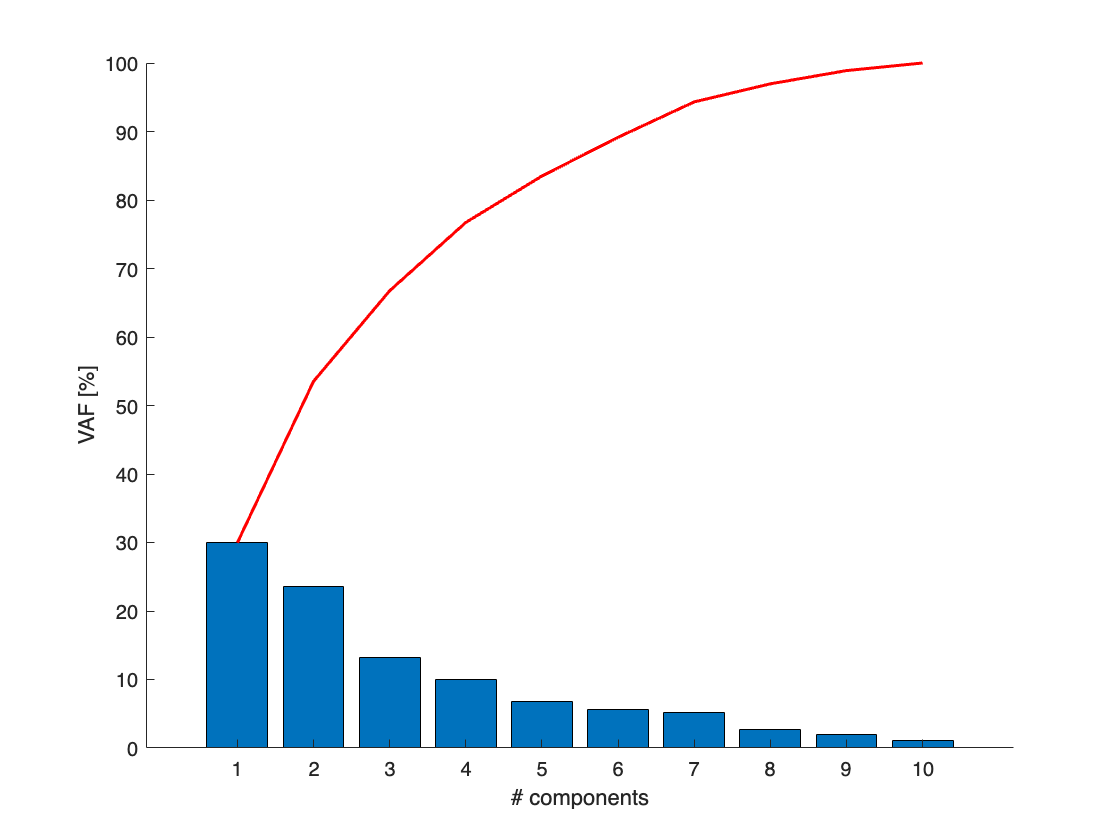

% Calculate Principal Component Analysis with Normalized Data
[coeff,score,latent,~,explained] = pca(X_);
[~,idx] = sort(explained,'descend');

% Visualization of variations
figure
bar(100.*latent./sum(latent))
hold on
plot(1:length(latent),100.*cumsum(latent)./sum(latent),'Color','r',"LineWidth",1.5)
hold off

xlabel('# components')
ylabel('VAF [%]')
box off

The heatmap indicates the distribution of the contributive features for each principal component.

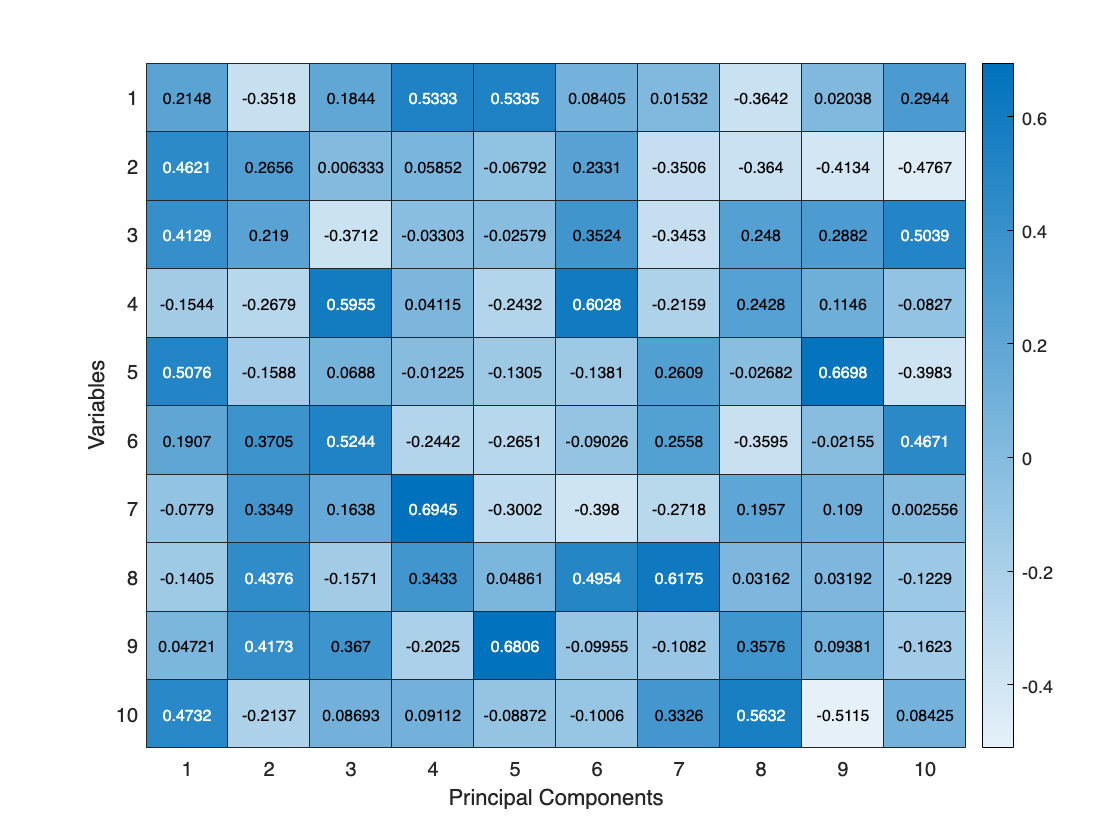

heatmap(coeff,'XLabel','Principal Components','YLabel','Variables');

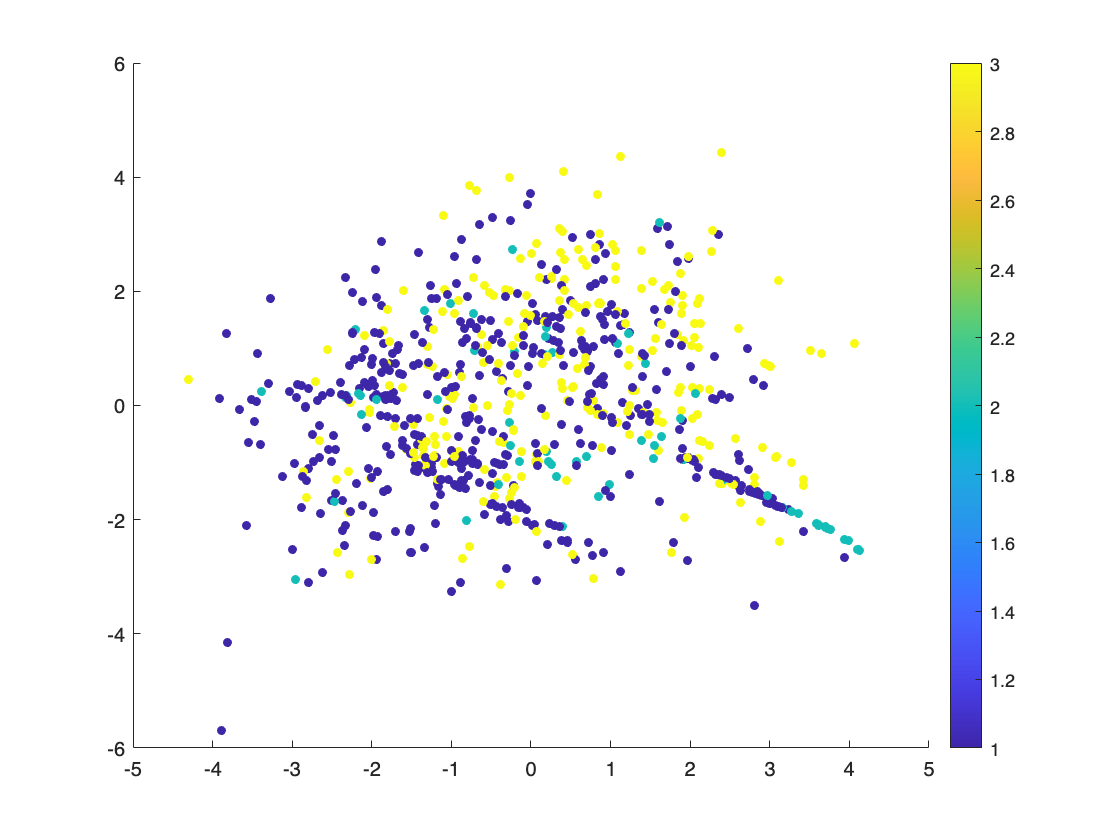

% Scatter the data depending on their class
figure
scatter((score(:,1)),(score(:,2)),20,Y,'filled')
colormap("default")
colorbar

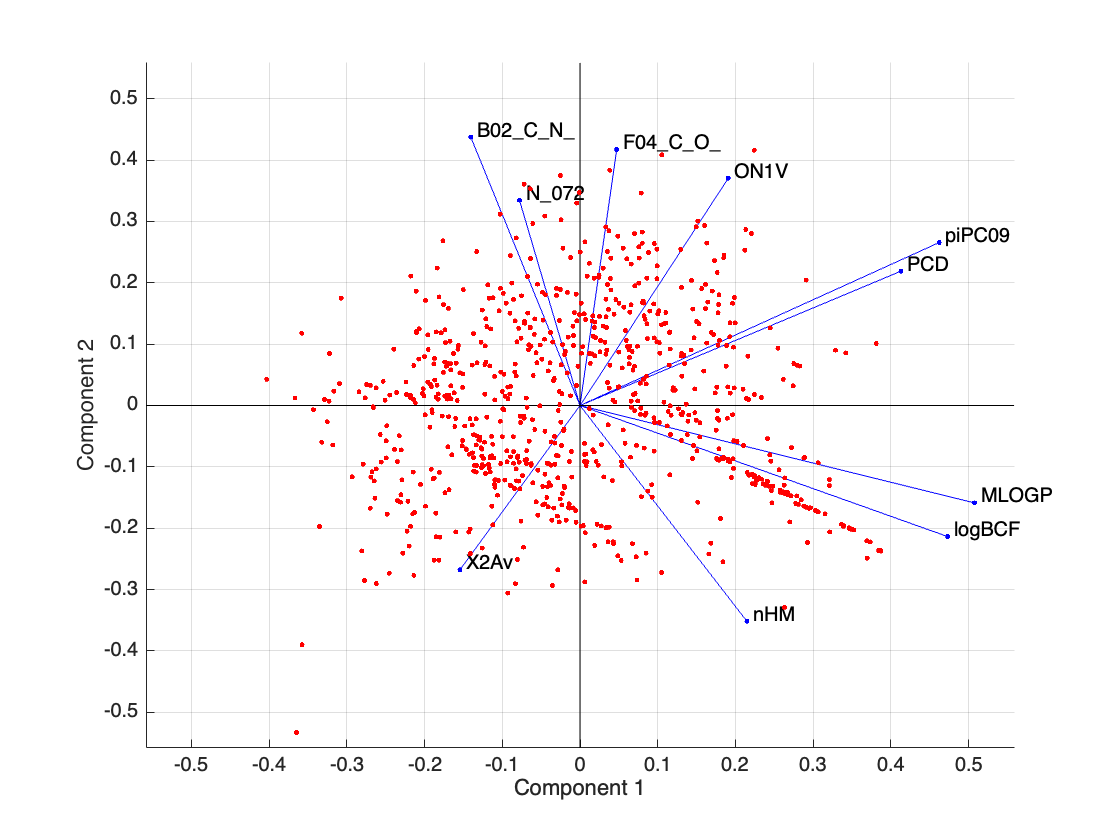

% Visualization of the biplot
figure
xlabel('score1')
ylabel('score2')
zlabel('score3')
box off
biplot(coeff(:,1:2),'scores',score(:,1:2),'varlabels',string(features_d));

### Train - Test Split

#### Train

% Pick the train data
train = data(find(string(data.Set)=='Train'),:);

% Separate the labels and the features
X_train = train(:,4:end);
X_train(:,'Class') = [];
Y_train = train(:,'Class');

#### Test

% Pick the test data
test = data(find(string(data.Set)=='Test'),:);

% Separate the labels and the features
X_test = test(:,4:end);
X_test(:,'Class') = [];
Y_test = test(:,'Class');

#### Change Data Type of the Train and Test Data

% Also convert the test and train data to array and categorical data to use
% some algorithms

X_te = table2array(X_test);
Y_te = categorical(string(table2array(Y_test)));

X_tr = table2array(X_train);
Y_tr = categorical(string(table2array(Y_train)));

#### Sizes of the Train and Test Data

s_te = size(Y_te,1);
s_tr = size(Y_tr,1);
Set = ["Train";"Test"];
Size= [s_tr;s_te];
Percentage = [100*s_tr/(s_tr+s_te);100*s_te/(s_tr+s_te)];
table(Set,Size,Percentage)

ans = 2×3 table
      Set      Size    Percentage
    _______    ____    __________

    "Train"    584       74.968  
    "Test"     195       25.032  


## Analysis Procedures

### Naive Bayes

Bayes Theorem provides a way of calculating posterior probability $p\left(C_k |X\right)$ from class prior probability$p\left(C_k \right)$, predictor prior probability$p\left(X\right)$, and likelihood$p\left(X|C_k \right)$.


$$p\left(C_k |X\right)=\frac{p\left(X|C_k \right)p\left(C_k \right)}{p\left(X\right)}$$


then


$$p\left(X|C_k \right)=p\left(x_1 ,\ldotp \ldotp \ldotp ,x_n |C_k \right)=\prod_{i=1}^n p\left(x_i |C_k \right)$$
 


$$p\left(C_k |X\right)=\frac{p\left(C_k \right)\prod_{i=1}^n p\left(x_i |C_k \right)}{p\left(X\right)}$$


Since the prior probability of predictor $p\left(X\right)$ is constant given the input:


$$p\left(C_k |X\right)\propto$$

$$p\left(C_k \right)\prod_{i=1}^n p\left(x_i |C_k \right)$$



$$\;C=\arg \;\max C_k \;\left\lbrack p\left(C\right)\prod_{i=1}^n p\left(x_i |C_k \right)\right\rbrack$$


There are three main types of Naive Bayes algorithms: Gaussian Naive  Bayes, Multinomial Naive Bayes, and Bernoulli Naive Bayes. Each of these algorithms uses different mathematical formulas to calculate the  probabilities required for the Bayes' theorem.

In Multinomial Naive Bayes, the features are discrete values representing the number of occurrences of words or similar units. Given a set of features $x$ and a class $y$, the probability of $x$ given $y$ (i.e., $p\left(x|y\right)$) is calculated as the product of the probabilities of each feature:


$$p\left(x|y\right)=p\left(x_1 |y\right)p\left(x_2 |y\right)\ldotp \ldotp \ldotp p\left(x_m |y\right)$$


where $x_i$ is the $i\;$th feature and $m$ is the number of features. The probability of each feature given the class $y$ is calculated as the number of occurrences of the feature in instances of class $y$ divided by the total number of occurrences of the feature in all instances:


$$p\left(x_i |y\right)=\frac{n_{\left\lbrace x_i ,y\right\rbrace } }{n_y }$$


where $n_{\left\lbrace x_i ,y\right\rbrace }$ is the number of occurrences of feature $x_i$ in instances of class $y$, and $n_y$ is the number of instances of class y. The final probability that a data point belongs to class $y$ given the features $x$ is calculated using Bayes' theorem as in Gaussian Naive Bayes.

Naive Bayes is a simple and efficient algorithm that can be used for classification tasks. Advantages of the of using it is that it requires less data to train and it can both handle **continuous and categorical features** that's why it is suitable for our data which is categorical [6].

% Calculate the Naive Bayes and get the model
Mdl = fitcnb(X_train,Y_train,'ClassNames',{'1','2','3'})

Mdl =   ClassificationNaiveBayes
            PredictorNames: {'nHM'  'piPC09'  'PCD'  'X2Av'  'MLOGP'  'ON1V'  'N_072'  'B02_C_N_'  'F04_C_O_'  'logBCF'}
              ResponseName: 'Class'
     CategoricalPredictors: []
                ClassNames: {'1'  '2'  '3'}
            ScoreTransform: 'none'
           NumObservations: 584
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {3×10 cell}


  Properties, Methods


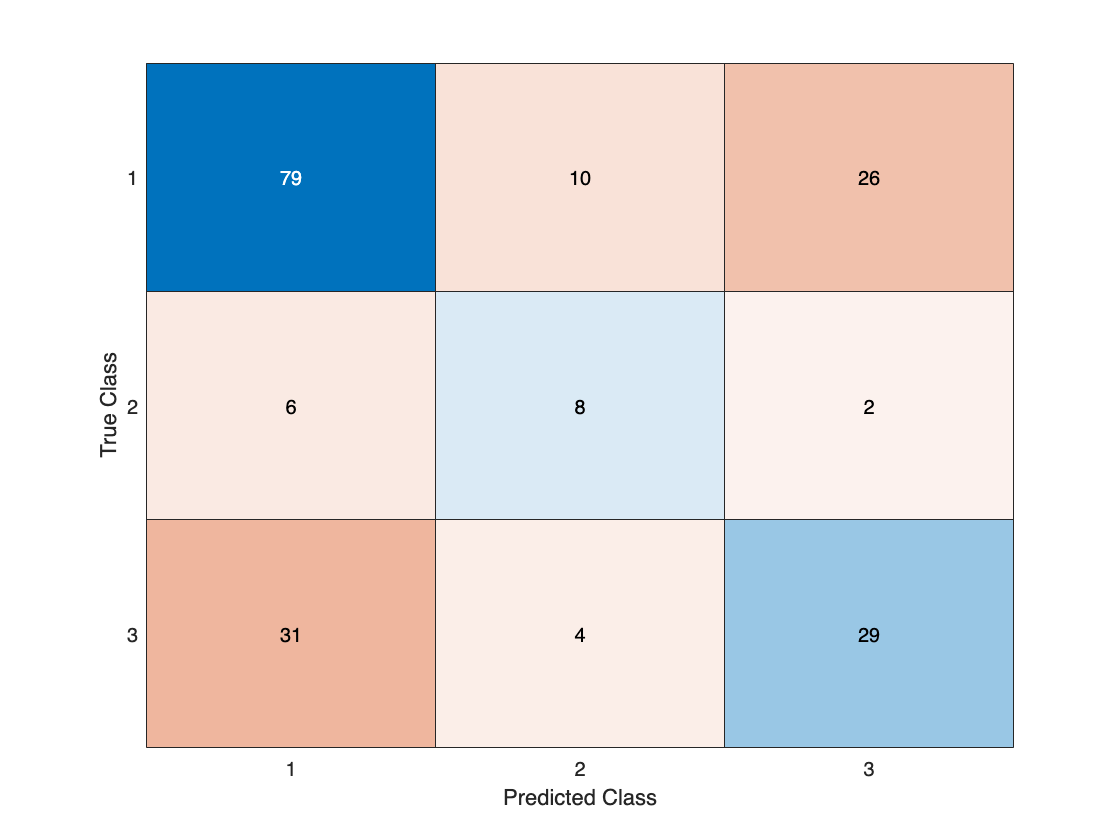

% Testing our model with "predict" function using Test Data
[y_predict,Posterior] = predict(Mdl,X_test);

% Calculate and plot Confusion Matrix
%hold off
result=confusionmat(Y_test.Class, str2double(y_predict));
chart=confusionchart(Y_test.Class, str2double(y_predict));

% Calculate the accuracy
acc_nvb = sum(str2double(y_predict) == int32(Y_te))/length(Y_te)

acc_nvb = 0.5949

#### ROC Curves and AUC Values

Receiver Operating Characteristic (ROC) curves and the Area Under the Curve (AUC) value are widely used tools for evaluating the performance of binary classifiers.

A ROC curve is a plot of the True Positive Rate (TPR) against the False Positive Rate (FPR) for different thresholds on the classifier's predictions. The TPR is defined as the proportion of positive instances that are correctly classified as positive, while the FPR is defined as the proportion of negative instances that are incorrectly classified as positive. The ROC curve allows us to visualize the trade-off between these two metrics for different levels of prediction confidence.

The AUC value is the area under the ROC curve and provides a single summary statistic that quantifies the overall performance of the classifier. An AUC value of 1.0 indicates a perfect classifier that correctly separates all positive instances from negative instances, while an AUC value of 0.5 indicates a classifier that performs no better than random chance.

In practice, ROC curves and AUC values are useful for evaluating classifiers when the class distribution is imbalanced or when the cost of false positives and false negatives are unequal. For example, in a medical diagnosis scenario, a false positive might be less serious than a false negative, and it may be more important to minimize false negatives. In such a scenario, a classifier that has a high TPR and a low FPR would be preferred, even if it results in a higher FPR overall [7].

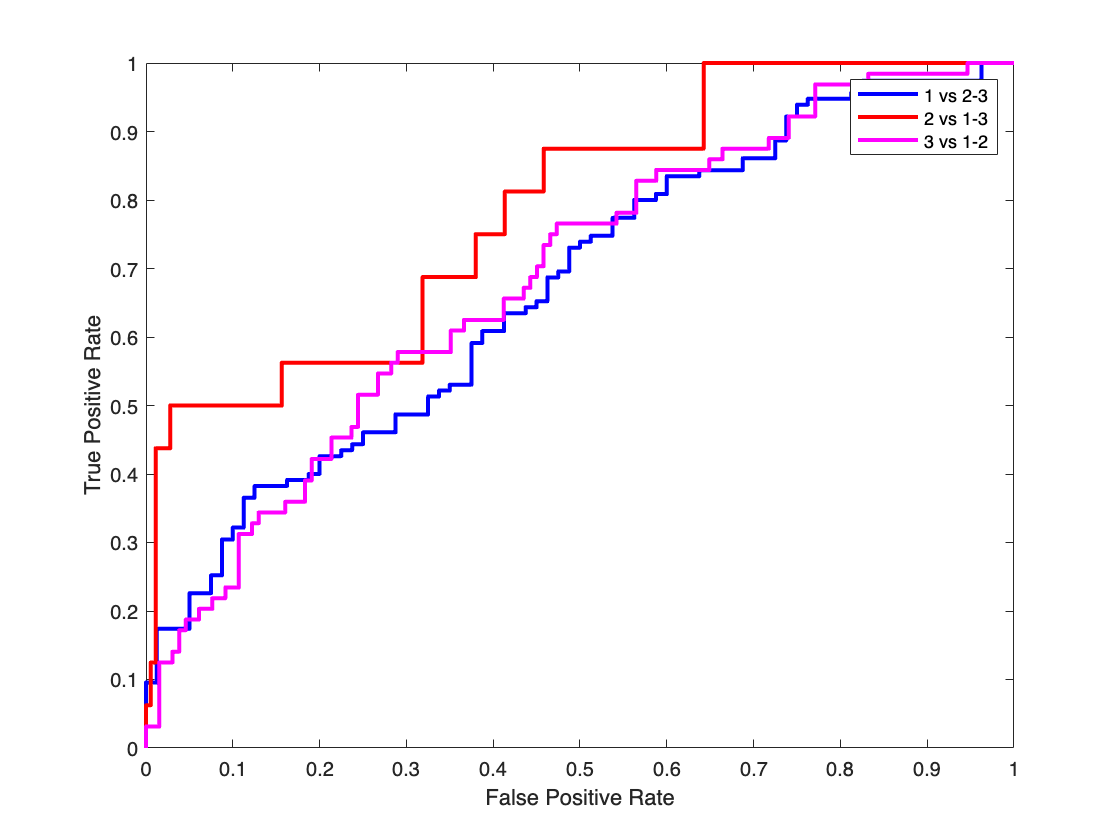

diffscore_1=zeros;
diffscore_2=zeros;
diffscore_3=zeros;
for i=1:size(Posterior,1)
    
    temp=Posterior(i,:);

    diffscore_1(i,:)=temp(1)-max([temp(2),temp(3)]);
    diffscore_2(i,:)=temp(2)-max([temp(1),temp(3)]);
    diffscore_3(i,:)=temp(3)-max([temp(1),temp(2)]);

end
% Calculate true positive rate and false positive rate for all classes
[X_1,Y_1,T_1,AUC_1] = perfcurve(Y_te,diffscore_1,'1');
[X_2,Y_2,T_2,AUC_2] = perfcurve(Y_te,diffscore_2,'2');
[X_3,Y_3,T_3,AUC_3] = perfcurve(Y_te,diffscore_3,'3');

% Plot ROC curves
figure
plot(X_1,Y_1,LineWidth=2,Color='b')
hold on
plot(X_2,Y_2,LineWidth=2,Color='r')
hold on
plot(X_3,Y_3,LineWidth=2,Color='m')
hold off
legend('1 vs 2-3','2 vs 1-3','3 vs 1-2')
xlabel('False Positive Rate')
ylabel('True Positive Rate')

AUC_name = ["AUC of 1 vs 2-3";"AUC of 2 vs 1-3";"AUC of 3 vs 1-2"];
AUC_NB = [AUC_1;AUC_2;AUC_3];
table(AUC_name,AUC_NB)

ans = 3×2 table
        AUC_name         AUC_NB 
    _________________    _______

    "AUC of 1 vs 2-3"    0.67076
    "AUC of 2 vs 1-3"    0.78631
    "AUC of 3 vs 1-2"    0.68476


#### **Drawbacks of using the Naive Bayes**

-  It assume that there is no correlation between the features which is a problematic approach since we have correlated data as we see in th PCA analysis

-  Sensitive for the noisy data 

Since Naive Bayes does not take account for dependency between features while training, it can poorly act with highly corralated data. In our case, we cannot say our data is highly correlated but it is certainly correlated, because of this even though we have a good accuracy our ROC curves and AUC values act poorly as can be seen from the figure above [8].

### Linear Discriminant Analysis (LDA) 

Linear Discriminant Analysis (LDA) is a supervised dimensionality reduction technique that is commonly used for classification problems. The main idea behind LDA is to project the high-dimensional data onto a lower-dimensional space while maximizing the separation between different classes. This can improve the performance of a classifier by reducing the dimensionality of the data while preserving the most important information for classification [9].


$$p\left(X|\mu ,\Sigma \right)=\frac{1}{{\left(2\pi \right)}^{\frac{d}{2}} {|\Sigma |}^{\frac{1}{2}} }\exp \left\lbrack -\frac{1}{2}{\left(X-\mu_i \right)}^T \Sigma^{-1} \left(X-\mu_i \right)\right\rbrack$$


$\mu$ is $d\times 1$ mean vector, $\Sigma$ is the $d\times d$ covariance matrix

In our case, we have a dataset with 10 features and 3 classes, so LDA can be a good choice for classifying the data because it can reduce the dimensionality of the data while preserving the most important information for classification.

Mdl_LDA = fitcdiscr(X_train,Y_train)

Mdl_LDA =   ClassificationDiscriminant
           PredictorNames: {'nHM'  'piPC09'  'PCD'  'X2Av'  'MLOGP'  'ON1V'  'N_072'  'B02_C_N_'  'F04_C_O_'  'logBCF'}
             ResponseName: 'Class'
    CategoricalPredictors: []
               ClassNames: [1 2 3]
           ScoreTransform: 'none'
          NumObservations: 584
              DiscrimType: 'linear'
                       Mu: [3×10 double]
                   Coeffs: [3×3 struct]


  Properties, Methods


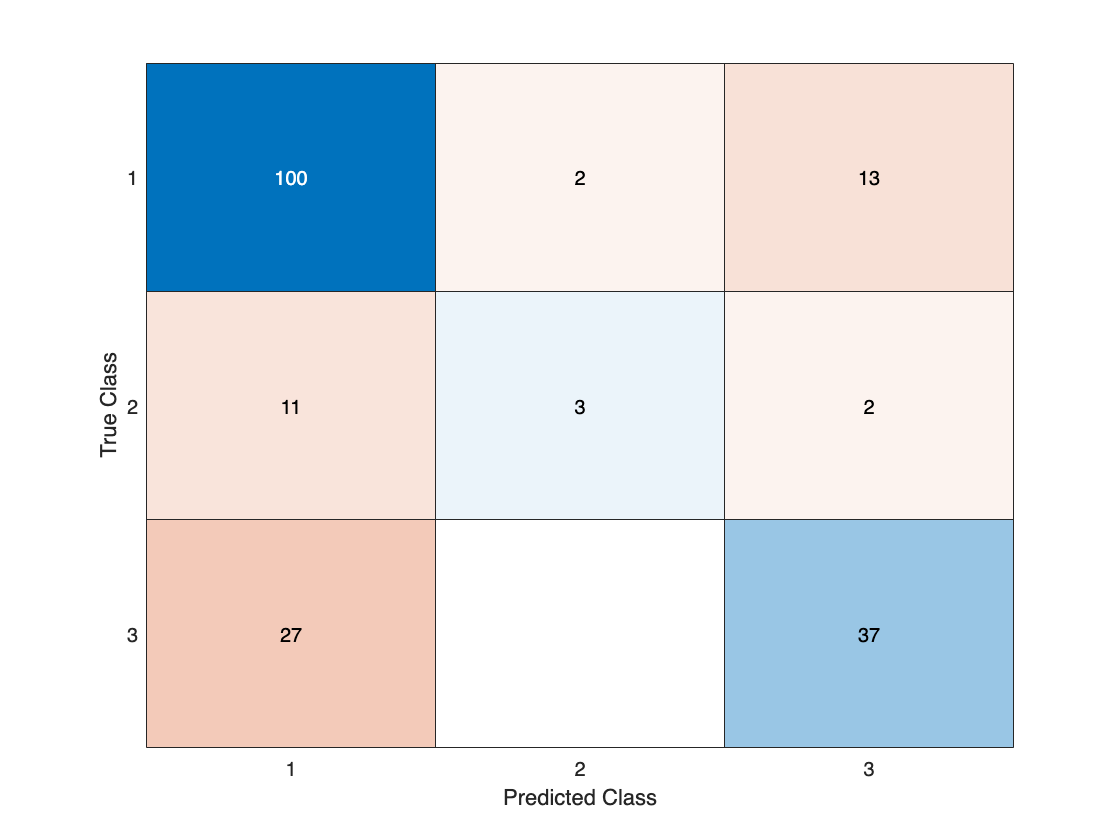

[y_predict,Posterior] = predict(Mdl_LDA,X_test);
result=confusionmat(Y_test.Class, y_predict);
chart=confusionchart(Y_test.Class, y_predict);

[~,pred_class] = max(double(y_predict),[],2);
acc_lda = sum(y_predict == int32(Y_te))/length(Y_te)

acc_lda = 0.7179

#### ROC Curves and AUC Values

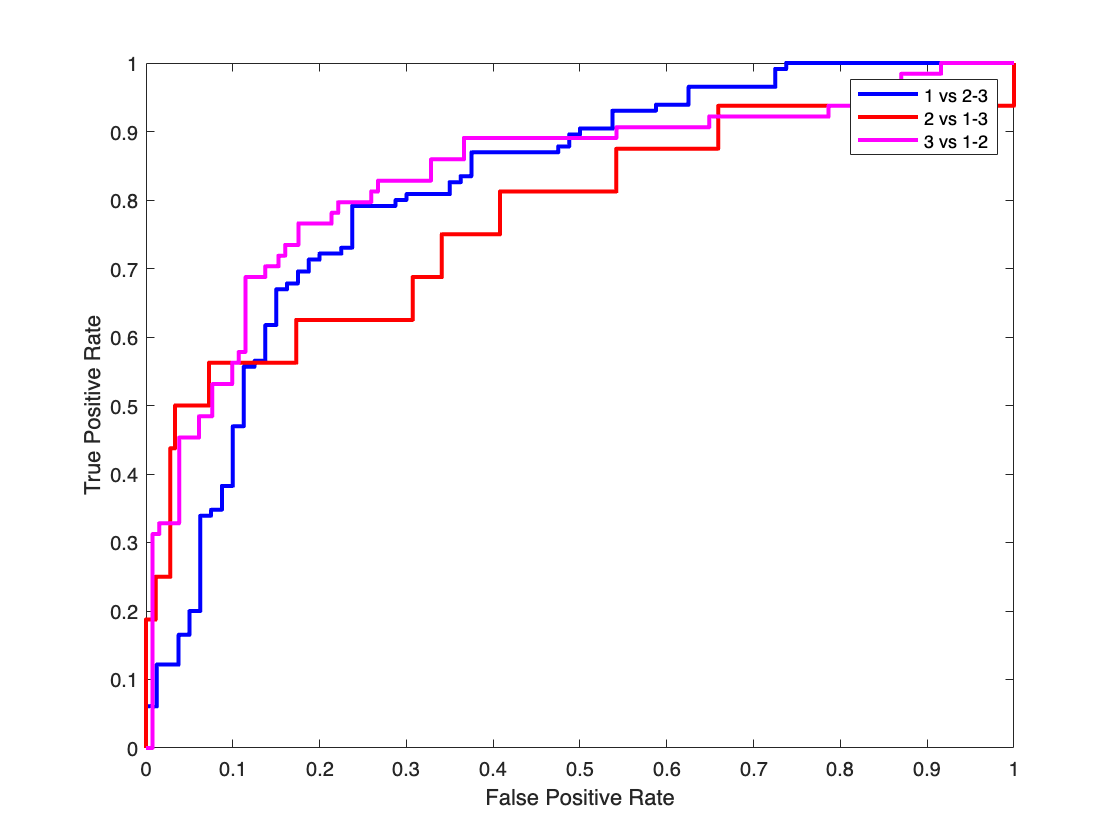

%roc curve
diffscore_1=zeros;
diffscore_2=zeros;
diffscore_3=zeros;
for i=1:size(Posterior,1)
    
    temp=Posterior(i,:);

    diffscore_1(i,:)=temp(1)-max([temp(2),temp(3)]);
    diffscore_2(i,:)=temp(2)-max([temp(1),temp(3)]);
    diffscore_3(i,:)=temp(3)-max([temp(1),temp(2)]);

end

% Calculate true positive rate and false positive rate for all classes
[X_1,Y_1,T_1,AUC_1] = perfcurve(Y_te,diffscore_1,'1');
[X_2,Y_2,T_2,AUC_2] = perfcurve(Y_te,diffscore_2,'2');
[X_3,Y_3,T_3,AUC_3] = perfcurve(Y_te,diffscore_3,'3');

% Plot ROC curves
figure
plot(X_1,Y_1,LineWidth=2,Color='b')
hold on
plot(X_2,Y_2,LineWidth=2,Color='r')
hold on
plot(X_3,Y_3,LineWidth=2,Color='m')
hold off

legend('1 vs 2-3','2 vs 1-3','3 vs 1-2')
xlabel('False Positive Rate')
ylabel('True Positive Rate')

AUC_name = ["AUC of 1 vs 2-3";"AUC of 2 vs 1-3";"AUC of 3 vs 1-2"];
AUC_LDA = [AUC_1;AUC_2;AUC_3];
table(AUC_name,AUC_LDA)

ans = 3×2 table
        AUC_name         AUC_LDA
    _________________    _______

    "AUC of 1 vs 2-3"    0.81793
    "AUC of 2 vs 1-3"    0.77304
    "AUC of 3 vs 1-2"     0.8354


#### Drawbacks of LDA

- It assumes that the data is normally distributed and that the covariance matrices for each class are equal. If this assumption is not met, the performance of the classifier may be poor. Therefore, it's important to check the data to make sure that it meets these assumptions before using LDA.

- LDA is sensitive to the scaling of the features, so it's important to standardize the data before applying LDA.

- LDA can be sensitive to the presence of outliers, which can have a large impact on the results [9].

### Logistic Regression

Multinomial logistic regression, also known as softmax regression or multinomial logit, is a variation of logistic regression used when the outcome variable is multiclass or ordinal (i.e. it has more than two possible outcomes). Instead of predicting a binary outcome, it predicts the probability of each possible outcome.

It is used to model the relationship between a set of independent variables and a categorical dependent variable with more than two categories [9],[10].

The general form of the multinomial logistic regression equation is given by:


$$p\left(y=k|x\right)=\frac{\exp \left(x\cdot \beta_k \right)}{\sum_{j=1}^k \exp \left(x\cdot \beta_j \right)}$$


where:

- $p\left(y=k|x\right)$ is the predicted probability of the dependent variable taking the value $k$, given the independent variables $x$

- $x$ is a vector of independent variables

- $\beta_k$ is a vector of coefficients for the $k\;$th class

- $k$ is the number of classes in the dependent variable

- the denominator is a normalizing term to ensure that the predicted probabilities for all classes sum up to 1

This formula gives us the predicted probabilities for each class, given a set of independent variables, and we can choose the class with the highest probability as the predicted class.

Advantages of multinomial logistic regression include:

It can handle,

-  Ordinal outcomes.

-  Multiple possible outcomes

-  Non-binary outcomes.

-  Non-normal distributions of the independent variables.

Drawbacks of multinomial logistic regression include:

- It requires large sample sizes to achieve stable results.

- It can't handle continuous-valued dependent variables.

- It may be sensitive to outliers.

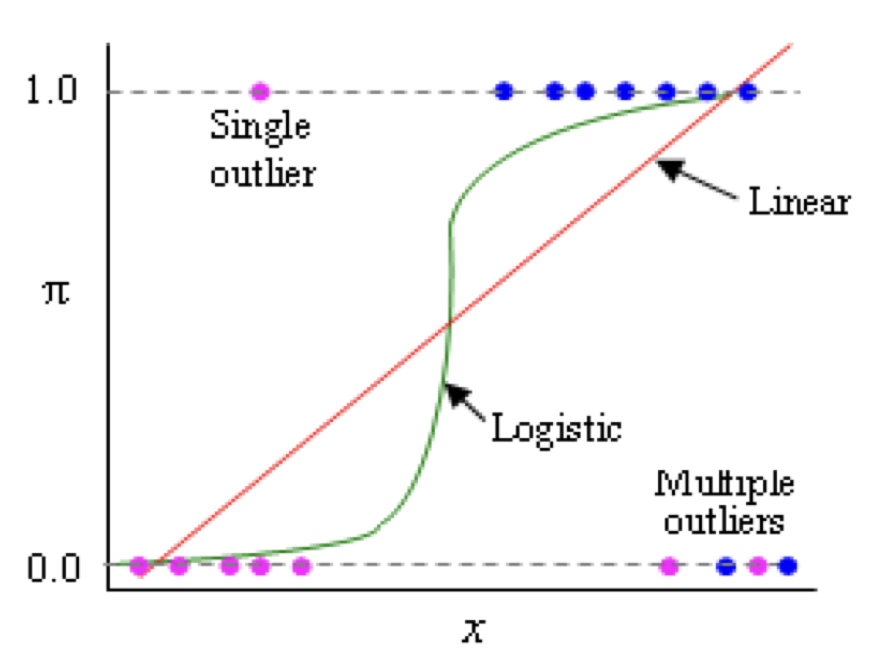

- It can't handle high dimensional categorical variables well.

- It assumes that the multiple classes are mutually exclusive, and that the observations are independent of each other.

% Fit the model
[B,dev,stats] = mnrfit(X_tr,Y_tr);

% Evaluate the model's performance on the test data
Posterior = mnrval(B,X_te);

% Calculate accuracy with the test data
[~,y_predicted] = max(Posterior,[],2);
acc_mnr = sum(y_predicted == int32(Y_te))/length(Y_te)

acc_mnr = 0.7590

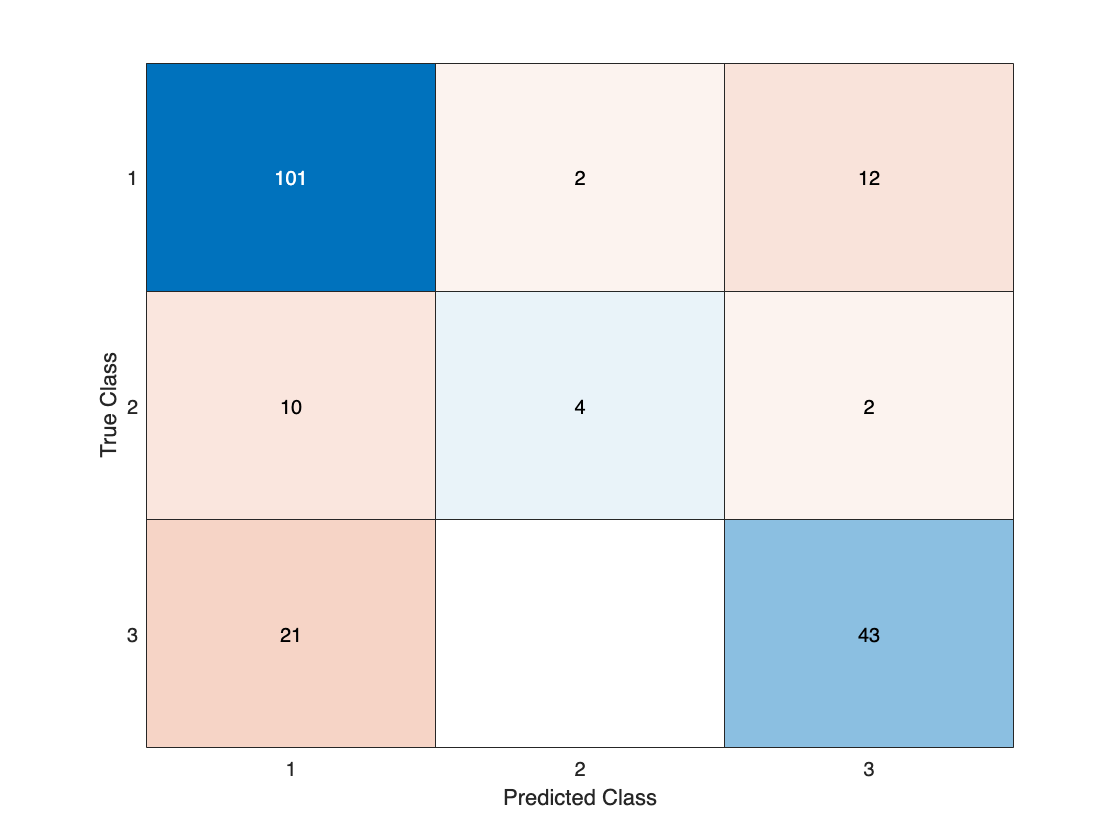

%result=confusionmat(Y_te, categorical(y_predicted)); This can also use for
%calculting the accuracy    
chart=confusionchart(Y_te,categorical(y_predicted));

#### ROC Curves and AUC Values

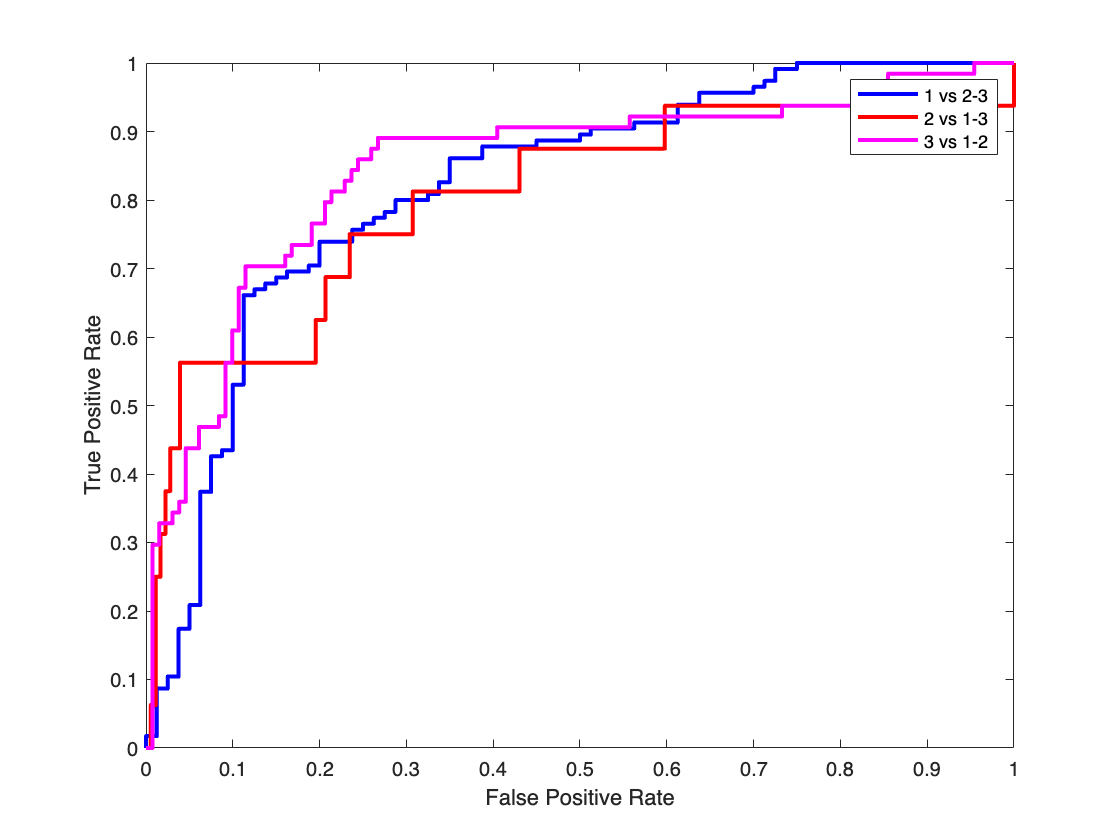

diffscore_1=zeros;
diffscore_2=zeros;
diffscore_3=zeros;

for i=1:size(Posterior,1)

    temp=Posterior(i,:);

    diffscore_1(i,:)=temp(1)-max([temp(2),temp(3)]);
    diffscore_2(i,:)=temp(2)-max([temp(1),temp(3)]);
    diffscore_3(i,:)=temp(3)-max([temp(1),temp(2)]);

end

% Calculate true positive rate and false positive rate for all classes
[X_1,Y_1,T_1,AUC_1] = perfcurve(Y_te,diffscore_1,'1');
[X_2,Y_2,T_2,AUC_2] = perfcurve(Y_te,diffscore_2,'2');
[X_3,Y_3,T_3,AUC_3] = perfcurve(Y_te,diffscore_3,'3');

% Plot ROC curves
figure
plot(X_1,Y_1,LineWidth=2,Color='b')
hold on
plot(X_2,Y_2,LineWidth=2,Color='r')
hold on
plot(X_3,Y_3,LineWidth=2,Color='m')
hold off
legend('1 vs 2-3','2 vs 1-3','3 vs 1-2')
xlabel('False Positive Rate')
ylabel('True Positive Rate')

AUC_name = ["AUC of 1 vs 2-3";"AUC of 2 vs 1-3";"AUC of 3 vs 1-2"];
AUC_LR = [AUC_1;AUC_2;AUC_3];
table(AUC_name,AUC_LR)

ans = 3×2 table
        AUC_name         AUC_LR 
    _________________    _______

    "AUC of 1 vs 2-3"    0.82185
    "AUC of 2 vs 1-3"    0.80272
    "AUC of 3 vs 1-2"    0.84578


### Deep Neural Networks (DNN)

Deep Neural Networks (DNNs) are a type of artificial neural network with multiple layers between the input and output layers. These multiple layers allow the network to learn and model complex relationships between the inputs and outputs. The layers in a DNN consist of interconnected nodes, each of which performs a simple mathematical operation on its inputs, called activation. The weights of the connections between the nodes are learned during the training process using an optimization algorithm, such as stochastic gradient descent [11].

The mathematical formula for a node in a DNN is as follows:


$$z=\sum w\ldotp x+b$$
 

where$z$ is the output of the node, $x$ is the input to the node, $w$ is the weight of the connection between the input and the node, and $b$ is the bias term.

The activation function is then applied to the output $z$ to produce the final node output a. The activation function introduces non-linearity into the network and allows the network to model complex relationships between the inputs and outputs. Common activation functions include the sigmoid function, the hyperbolic tangent function, and the Rectified Linear Unit (ReLU) function.

In a multi-layer DNN, the output of one layer serves as the input to the next layer, and the process is repeated until the final layer produces the output of the network. The weights and biases of the connections between the nodes are learned during the training process to minimize the error between the network's predictions and the ground-truth labels.

During the training process, cross-validation was used to evaluate the performance of the network using a separate test dataset. The results of the training indicate a small degree of overfitting, as seen in the graph of the performance metrics. Despite this, the network achieved an accuracy of 73.3%. The network had a total of 2.7k learnable parameters. To address the issue of overfitting, various techniques were employed such as using a dropout layer and implementing weight initialization methods. The network also used rectified linear units (ReLU) as the activation function and stochastic gradient descent with momentum (SGDM) as the optimization algorithm. These techniques helped to improve the overall performance of the network and reduce overfitting."

The overfitting issue is a common problem in neural networks, but with the use of regularization techniques such as dropout and weight initialization, the network achieved a relatively good accuracy of 73.3% compare to the LDA and Naive Bayes approaches.

It's important to note that the number of learnable parameters in a neural network is a crucial factor that can affect its performance. A high number of parameters can lead to overfitting, and a low number can lead to underfitting, so it's a good idea to keep track of the number of learnable parameters in your network. In this case, 2.7k is a relatively small number of parameters, which could contribute to the good performance of the network.

It's also worth noting that the use of ReLU and SGDM as the activation function and optimizer respectively, could be a good choice for this problem and they may have contributed to the good performance of the network.

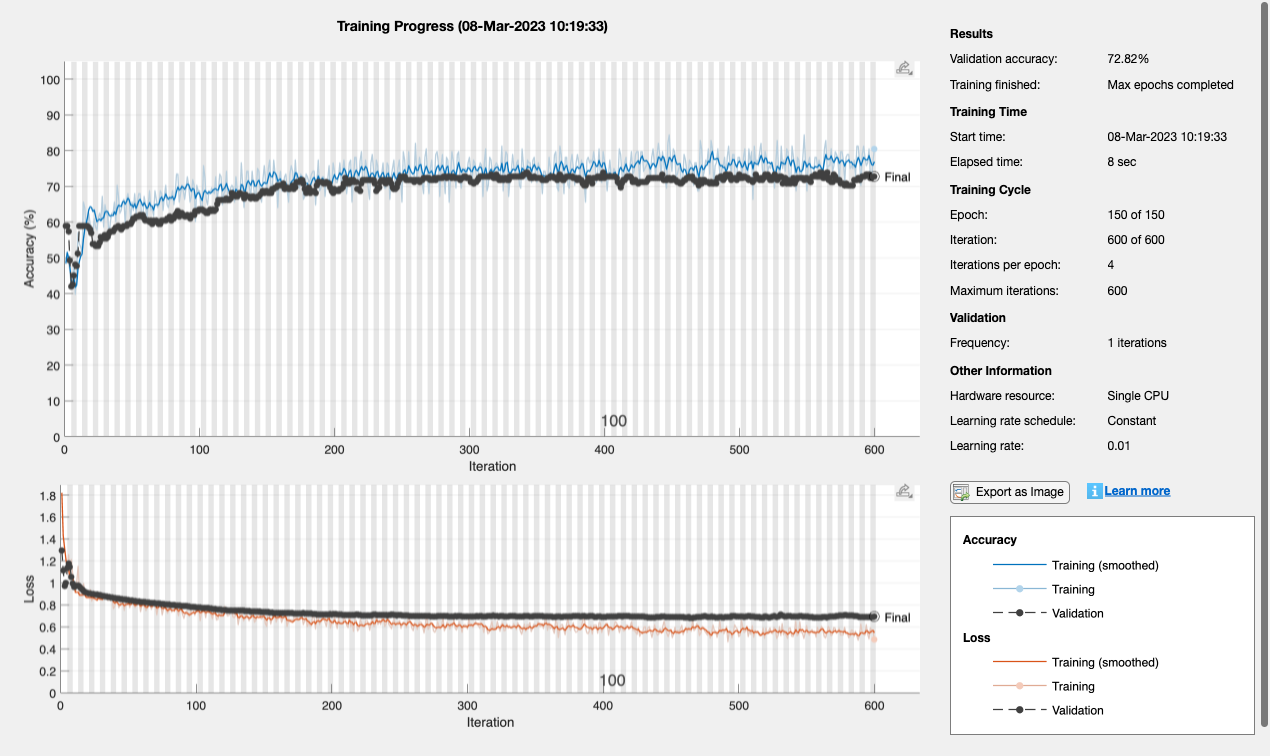

numClasses = 3;
layers = [
    featureInputLayer(10,"Name","featureinput")
    fullyConnectedLayer(16,"Name","fc_0",'WeightsInitializer','glorot')
    reluLayer
    dropoutLayer(0.1) 
    fullyConnectedLayer(128,"Name","fc_1",'WeightsInitializer','glorot')
    reluLayer
    dropoutLayer(0.5) 
    fullyConnectedLayer(numClasses,'WeightsInitializer','glorot')
    softmaxLayer
    classificationLayer];

options = trainingOptions("sgdm", ...
    MaxEpochs=150, ...
    ValidationData={X_te,Y_te}, ...
    ValidationFrequency=1, ...
    Verbose=false, ...
    Shuffle="once", ...
    Plots="training-progress");

% Train the DNN 
net = trainNetwork(X_tr, Y_tr, layers, options);

analyzeNetwork(net)

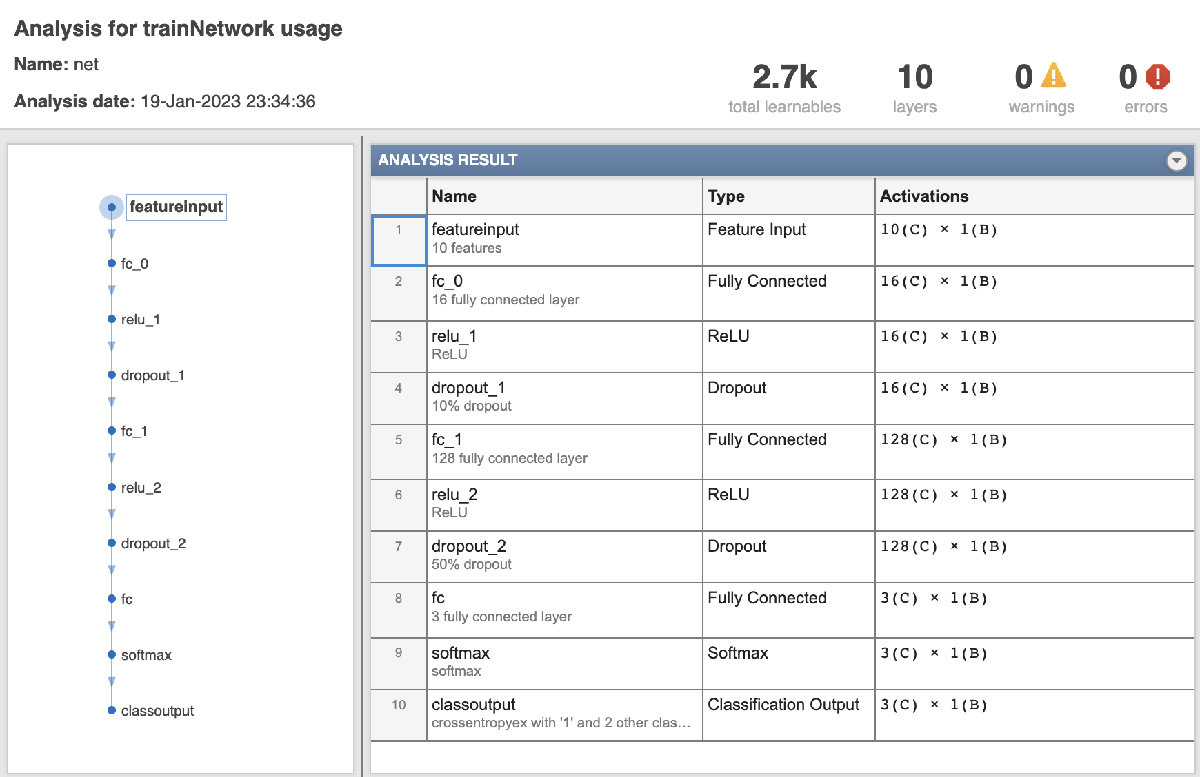

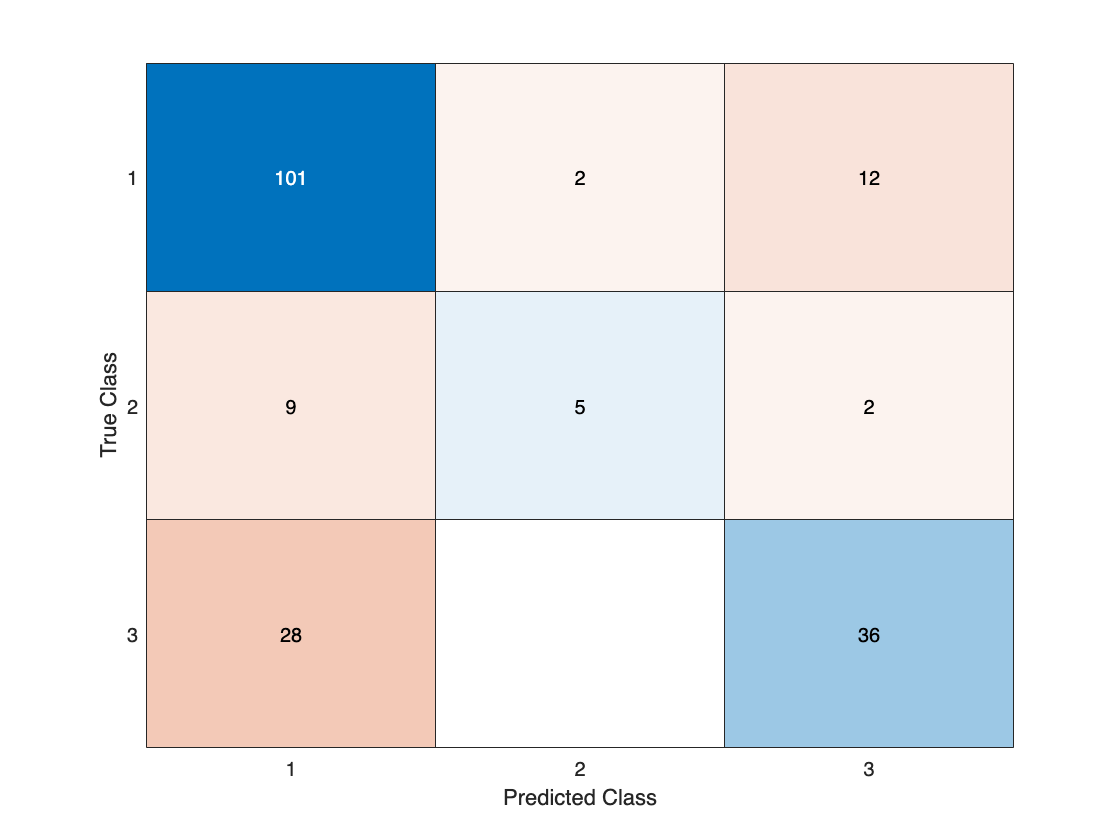

[y_predicted,scores] = classify(net,X_test);
chart=confusionchart(Y_test.Class,double(y_predicted));

acc_dnn = sum(int32(y_predicted) == int32(Y_te))/length(Y_te)

acc_dnn = 0.7282

#### ROC Curve of the DNN

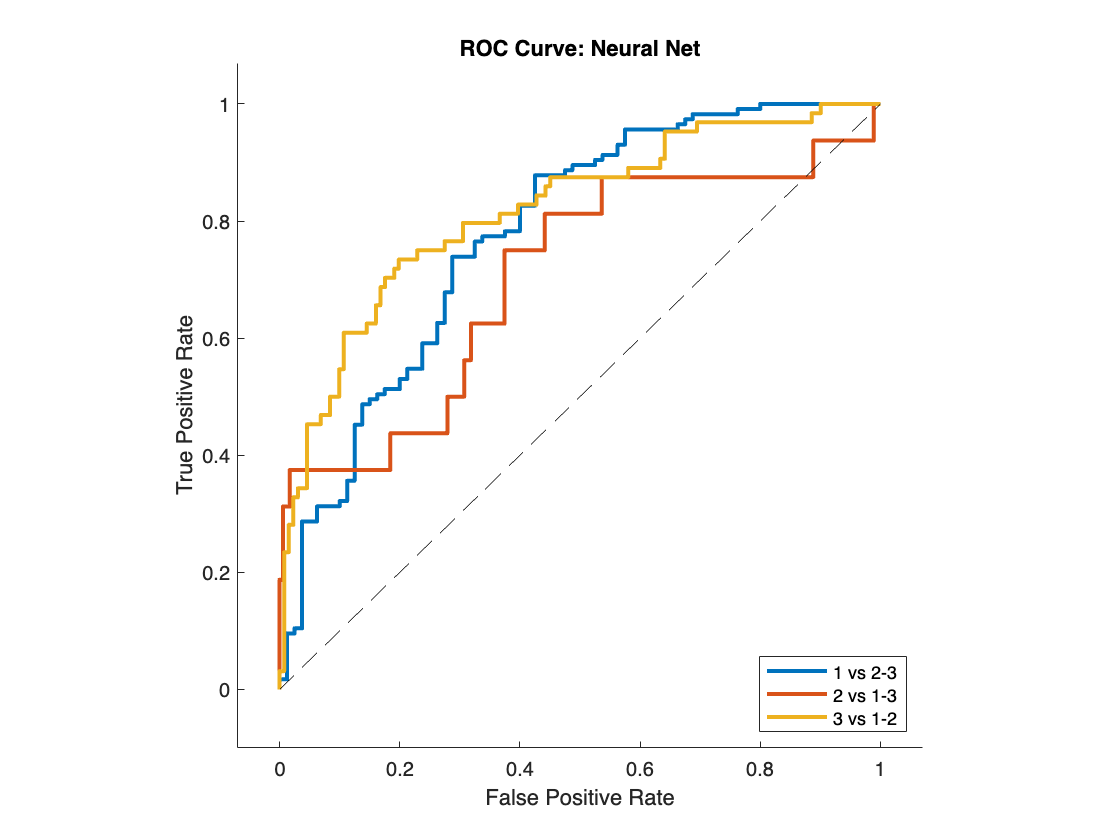

classNames = net.Layers(end).Classes;
rocNet = rocmetrics(Y_te,scores,classNames);
AUC_DNN = rocNet.AUC;
figure
plot(rocNet,'Linewidth',2,ShowModelOperatingPoint=false)
legend('1 vs 2-3','2 vs 1-3','3 vs 1-2')
title("ROC Curve: Neural Net")

## Results

### Test Accuracy Comparison

#### Table Representation

Method = ["Naive Bayes";"Linear Discriminant Analysis";"Multinomial Logistic Regression";"Deep Neural Network"];
Test_Accuracy = [acc_nvb;acc_lda;acc_mnr;acc_dnn;];
table(Method,Test_Accuracy)

ans = 4×2 table
                 Method                  Test_Accuracy
    _________________________________    _____________

    "Naive Bayes"                           0.59487   
    "Linear Discriminant Analysis"          0.71795   
    "Multinomial Logistic Regression"       0.75897   
    "Deep Neural Network"                   0.72821   


#### Bar Plot Representation

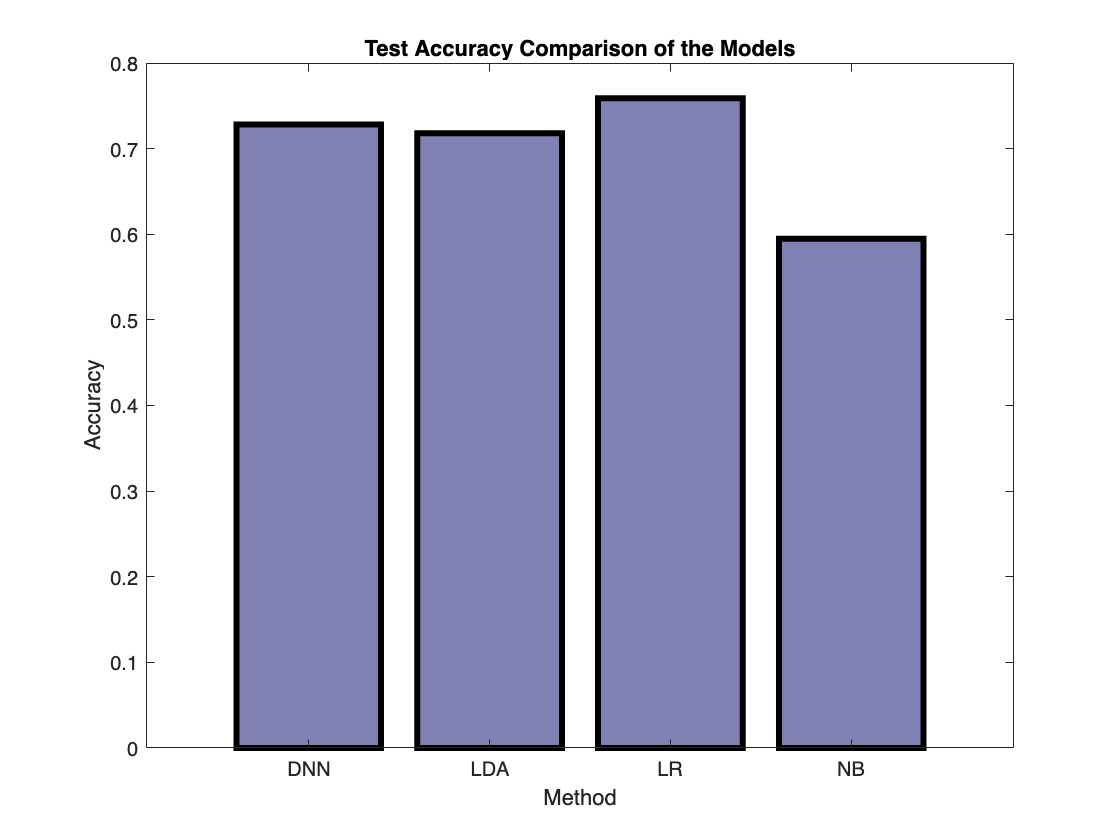

Method = ["Naive Bayes";"Linear Discriminant Analysis";"Multinomial Logistic Regression";"Deep Neural Network"];
acc= cat(2, acc_nvb,acc_lda,acc_mnr,acc_dnn);
classNames = categorical({'NB','LDA','LR','DNN'});
figure
bar(classNames,acc,'FaceColor',[.5 .5 .7],'EdgeColor',[.0 .0 .0],'LineWidth',3)
xlabel("Method")
ylabel("Accuracy")
title("Test Accuracy Comparison of the Models")

### AUC (Area Under Curve) Comparison

#### Table Representation

Method = ["Naive Bayes";"Linear Discriminant Analysis";"Multinomial Logistic Regression";"Deep Neural Network"];
AUC= cat(2, AUC_NB, AUC_LDA, AUC_LR, AUC_DNN');
AUC_Values = AUC';
table(Method,AUC_Values)

ans = 4×2 table
                 Method                           AUC_Values          
    _________________________________    _____________________________

    "Naive Bayes"                        0.67076    0.78631    0.68476
    "Linear Discriminant Analysis"       0.81793    0.77304     0.8354
    "Multinomial Logistic Regression"    0.82185    0.80272    0.84578
    "Deep Neural Network"                0.77826    0.70496    0.81703


#### Bar Plot Representation

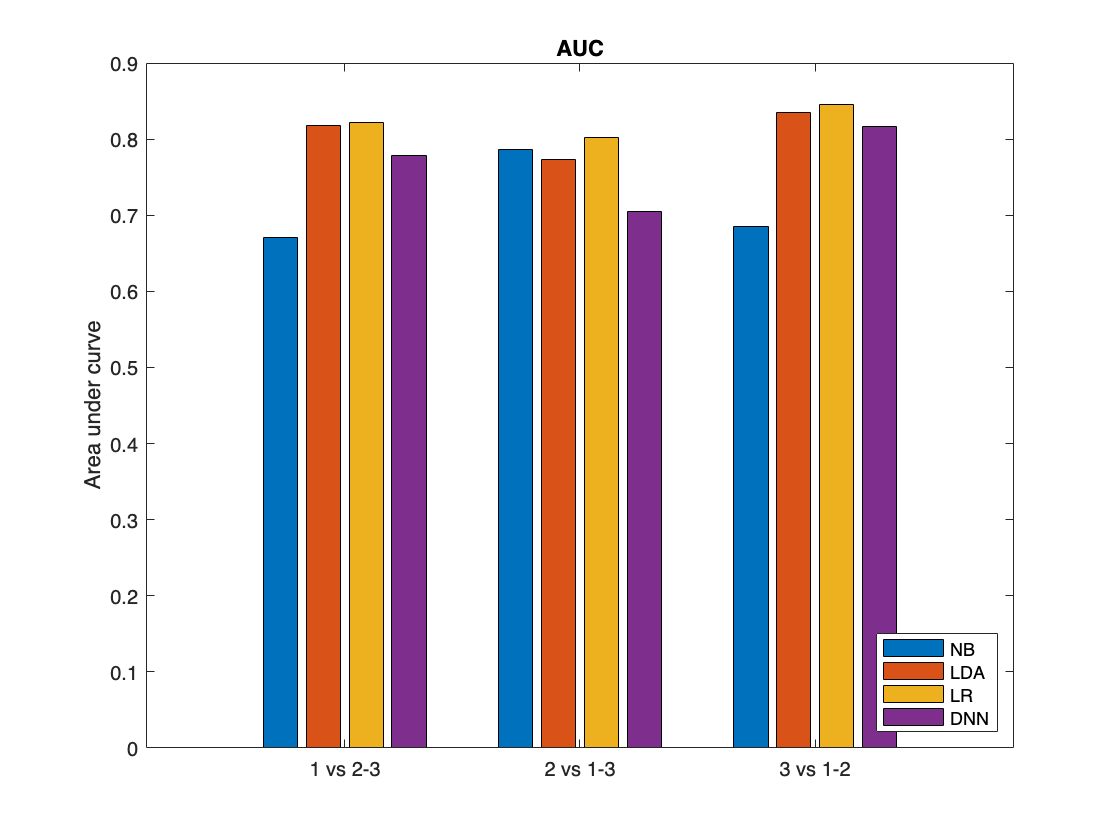

figure
classNames = categorical({'1 vs 2-3','2 vs 1-3','3 vs 1-2'});
bar(classNames,AUC)
ylabel("Area under curve")
legend(["NB","LDA","LR","DNN"],Location="southeast")
title("AUC")

## Discussion and Conclusions

The reason for a high accuracy in a particular method on a database X in bioconcentration with 10 significant features: nHM, piPC09, PCD, X2Av, MLOGP, ON1V, N.072, B02[C-N], F04[C-O], logBCF depends on several factors, such as the size and complexity of the database, the distribution of the data, and the relationships between the features and the target class.

Naive Bayes is a probabilistic algorithm that makes predictions based on the probabilities of different outcomes given the input features. If the 10 significant features in bioconcentration are uncorrelated and the data is linearly separable, Naive Bayes may produce high accuracy results.

Linear Discriminant Analysis (LDA) is a linear classifier that seeks to find the linear combination of features that best separates the classes. If the 10 significant features in bioconcentration are linearly separable and the data is normally distributed, LDA may produce high accuracy results.

Multinomial Logistic Regression is a statistical method for binary and multiclass classification problems. It models the relationship between the input features and the target class by estimating the probabilities of each class given the input features. If the relationships between the 10 significant features and the target class in bioconcentration are approximately linear, logistic regression may produce high accuracy results.

Deep Neural Networks (DNNs) are a type of artificial neural network that can model complex non-linear relationships between the inputs and outputs. DNNs are often used for tasks such as image and speech recognition and can achieve high accuracy on large and complex databases. If the relationships between the 10 significant features in bioconcentration and the target class are complex and non-linear, DNNs may be able to produce high accuracy results.

In conclusion, the choice of machine learning method for bioconcentration will depend on the properties of the 10 significant features and the relationship between the features and the target class. It is likely that different methods will perform better or worse based on these factors, and it is recommended to try multiple methods and compare their performance to determine the best approach for a given problem, which in this case by resault of test accuracy and AUC Comparison the best method for our data truns out to be Multinomial Logistic Regression.

## Bibliography

[1] Bioconcentration. (2022, November 12). In *Wikipedia*. [https://en.wikipedia.org/wiki/Bioconcentration](https://en.wikipedia.org/wiki/Bioconcentration)

[1] Wildman, S. A., & Crippen, G. M. (1999). Prediction of physicochemical parameters by atomic contributions. *Journal of chemical information and computer sciences*, *39*(5), 868-873.

[2] Partition coefficient. (2022, November 9). In *Wikipedia*. [https://en.wikipedia.org/wiki/Partition_coefficient](https://en.wikipedia.org/wiki/Partition_coefficient)

[2]Arnot, J. A., & Gobas, F. A.  (2006). A review of bioconcentration factor (BCF) and bioaccumulation  factor (BAF) assessments for organic chemicals in aquatic organisms. *Environmental Reviews*, *14*(4), 257-297.

[3] Grisoni, F., Consonni, V., Vighi, M., Villa, S., & Todeschini, R. (2016). Investigating the mechanisms of bioconcentration through QSAR classification trees. *Environment International*, *88*, 198–205. https://doi.org/10.1016/j.envint.2015.12.024 

[4] Grisoni, F., Consonni, V., Villa, S., Vighi, M., & Todeschini, R. (2015). QSAR models for bioconcentration: Is the increase in the complexity justified by more accurate predictions? *Chemosphere*, *127*, 171–179. https://doi.org/10.1016/j.chemosphere.2015.01.047 

[5] Bro, R., & Smilde, A. K. (2014). Principal component analysis. *Analytical methods*, *6*(9), 2812-2831.

[6] Murphy, K. P. (2012). Machine Learning, A Probabilistic Perspective, Kevin P. Murphy.

[7] Fawcett, T. (2006). An introduction to ROC analysis. *Pattern recognition letters*, *27*(8), 861-874.

[8] Zhang, H. (2004). The optimality of naive Bayes. *Aa*, *1*(2), 3.

[9] Hastie, T., Tibshirani, R., Friedman, J. H., & Friedman, J. H. (2009). *The elements of statistical learning: data mining, inference, and prediction* (Vol. 2, pp. 1-758). New York: springer.

[10] Bishop, C. M., & Nasrabadi, N. M. (2006). *Pattern recognition and machine learning* (Vol. 4, No. 4, p. 738). New York: springer.

[11] Schmidhuber, J. (2015). Deep learning in neural networks: An overview. *Neural networks*, *61*, 85-117.